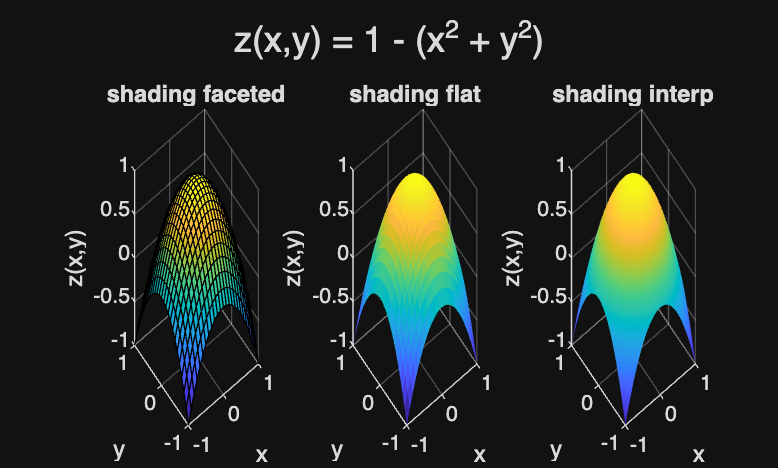

%% VILNIUS TECH EF - Skriptinis programavimas - 4 LD, 11 variantas
%  Rezultatu grafinis 3D atvaizdavimas
clear; clc; close all;

%% a) f(x,y) = 1 - 2x^2 - 3y^2,  x = r*cos(theta), y = r*sin(theta)
f1 = @(x, y) 1 - 2*x.^2 - 3*y.^2;      % funkcija kaip anoniminis handle

theta = linspace(0, 2*pi, 60);          % kampas 0..2pi
r     = linspace(0, 1, 30);             % spindulys 0..1
[R, T] = meshgrid(r, theta);            % poliarinis tinklelis (60x30)

X  = R .* cos(T);                       % poliarines -> Dekarto
Y  = R .* sin(T);
Z1 = f1(X, Y);

figure('Name', '4 LD - a) dalis');
h1 = surf(X, Y, Z1);                    % pavirsiaus grafikas
colormap(gca, winter);                  % spalvu palete siai asiai
shading interp;                         % tolygus spalvu perejimas
rotate(h1, [0 0 1], 50, [0 0 0]);       % pasukimas xy plokstumoje 50 laipsniu
axis tight; grid on; colorbar;
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
title('a) f(x,y) = 1 - 2x^2 - 3y^2,  x = r cos\theta,  y = r sin\theta');
view(3);

%% b) f(x,y) = sin(x^2 + y^2),  x, y - atsitiktiniai taskai
f2 = @(x, y) sin(x.^2 + y.^2);

N = 200;
x = (2*rand(1, N) - 1) .* sqrt(pi/2);   % 200 atsitiktiniu reiksmiu intervale (-sqrt(pi/2); sqrt(pi/2))
y = (2*rand(1, N) - 1) .* sqrt(pi/2);

[X2, Y2] = meshgrid(sort(x), sort(y));  % surikiuojam, kad tinklelis butu monotoniskas
Z2 = f2(X2, Y2);

figure('Name', '4 LD - b) dalis');
h2 = surf(X2, Y2, Z2);
colormap(gca, autumn);
shading interp;
rotate(h2, [0 0 1], 30, [0 0 0]);       % pasukimas xy plokstumoje 30 laipsniu
axis tight; grid on; colorbar;
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
title('b) f(x,y) = sin(x^2 + y^2)');
view(3);

%% VILNIUS TECH EF - Skriptinis programavimas - 4 LD, 11 variantas
%  Rezultatu grafinis 3D atvaizdavimas
clear; clc; close all;

%% P. Funkcijos shading savybes: z(x,y) = 1 - (x^2 + y^2)
fP = @(x, y) 1 - (x.^2 + y.^2);
[XP, YP] = meshgrid(linspace(-1, 1, 25));   % kvadratinis tinklelis [-1;1] x [-1;1]
ZP = fP(XP, YP);

rezimai = {'faceted', 'flat', 'interp'};    % trys shading rezimai
figure('Name', '4 LD - P dalis (shading)');
for k = 1:numel(rezimai)
    subplot(1, 3, k);                       % 1 eilute, 3 stulpeliai, k-tasis langelis
    surf(XP, YP, ZP);
    shading(rezimai{k});
    colormap(gca, parula);
    axis tight; grid on;
    xlabel('x'); ylabel('y'); zlabel('z(x,y)');
    title(['shading ' rezimai{k}]);
end
sgtitle('z(x,y) = 1 - (x^2 + y^2)');

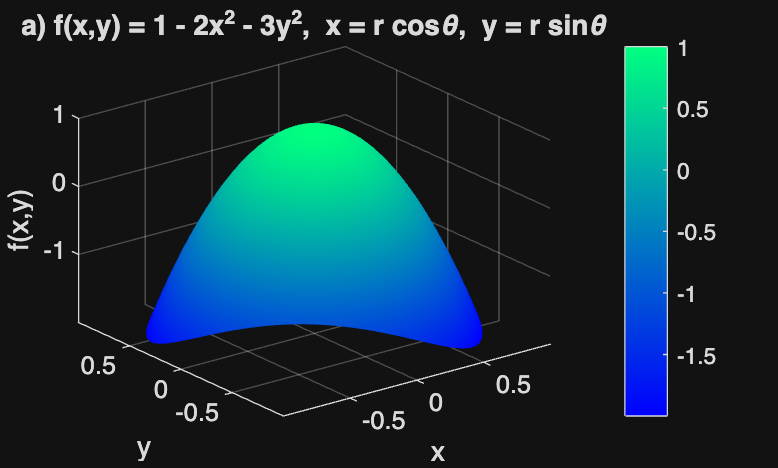


%% a) f(x,y) = 1 - 2x^2 - 3y^2,  x = r*cos(theta), y = r*sin(theta)
f1 = @(x, y) 1 - 2*x.^2 - 3*y.^2;      % funkcija kaip anoniminis handle

theta = linspace(0, 2*pi, 60);          % kampas 0..2pi
r     = linspace(0, 1, 30);             % spindulys 0..1
[R, T] = meshgrid(r, theta);            % poliarinis tinklelis (60x30)

X  = R .* cos(T);                       % poliarines -> Dekarto
Y  = R .* sin(T);
Z1 = f1(X, Y);

figure('Name', '4 LD - a) dalis');
h1 = surf(X, Y, Z1);                    % pavirsiaus grafikas
colormap(gca, winter);                  % spalvu palete siai asiai
shading interp;                         % tolygus spalvu perejimas
rotate(h1, [0 0 1], 50, [0 0 0]);       % pasukimas xy plokstumoje 50 laipsniu
axis tight; grid on; colorbar;
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
title('a) f(x,y) = 1 - 2x^2 - 3y^2,  x = r cos\theta,  y = r sin\theta');
view(3);

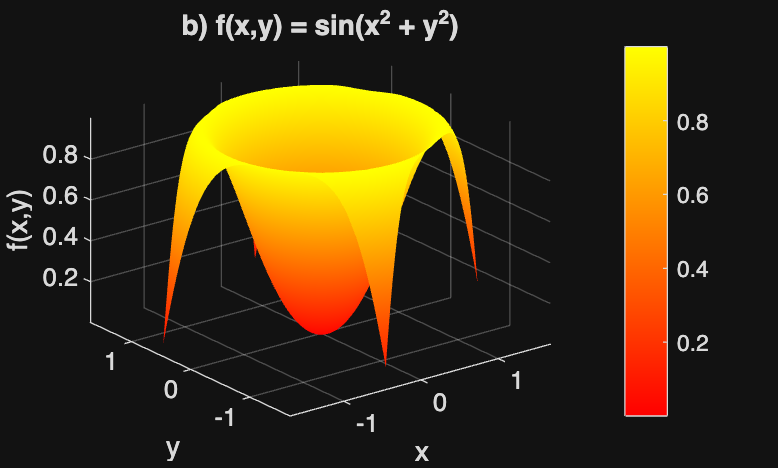


%% b) f(x,y) = sin(x^2 + y^2),  x, y - atsitiktiniai taskai
f2 = @(x, y) sin(x.^2 + y.^2);

N = 200;
x = (2*rand(1, N) - 1) .* sqrt(pi/2);   % 200 atsitiktiniu reiksmiu intervale (-sqrt(pi/2); sqrt(pi/2))
y = (2*rand(1, N) - 1) .* sqrt(pi/2);

[X2, Y2] = meshgrid(sort(x), sort(y));  % surikiuojam, kad tinklelis butu monotoniskas
Z2 = f2(X2, Y2);

figure('Name', '4 LD - b) dalis');
h2 = surf(X2, Y2, Z2);
colormap(gca, autumn);
shading interp;
rotate(h2, [0 0 1], 30, [0 0 0]);       % pasukimas xy plokstumoje 30 laipsniu
axis tight; grid on; colorbar;
xlabel('x'); ylabel('y'); zlabel('f(x,y)');
title('b) f(x,y) = sin(x^2 + y^2)');
view(3);